# MRC a MRAC

Identifikovane polynomy

pGain = [-7.74558355399971e-09 7.92523655765039e-06 -0.00291980737503381 0.463728547328537 -23.1386227555553];
pT = [1.10661505286941e-07 -5.48243874702451e-05 0.00740611980939077 -0.00882197108389277];
p = [1.27264127791514e-06,-0.000693202019254355,0.101241610731183,5.53942212609170,-881.974593934446];
pK = [6.06868337517324e-06,-0.00276839370282041,0.349669070323109,-3.90147463042572];

## Všeobecné

Urcenie parametrov v pracovnom bode

%parametre odcitane z pracovneho bodu
upb = 206

upb = 206

upb_delta = 25;
ypb = polyval(pGain,upb)*upb

ypb = 786.3259


T = polyval(pT,upb)

T = 0.1577

K = polyval(pK,upb)

K = 3.7021


a0 = 1/T

a0 = 6.3414

b0 = K/T

b0 = 23.4766

Referencny model

am = 3;
bm = 3;

Urcenie parametrov zakona riadenia (P regulator)

theta1_ideal = (a0-am)/b0

theta1_ideal = 0.1423

theta2_ideal = bm/b0

theta2_ideal = 0.1278

## MRC riadenie

Simulacia

clf;
out = sim('MRC_regulator.slx');

Vykreslenie

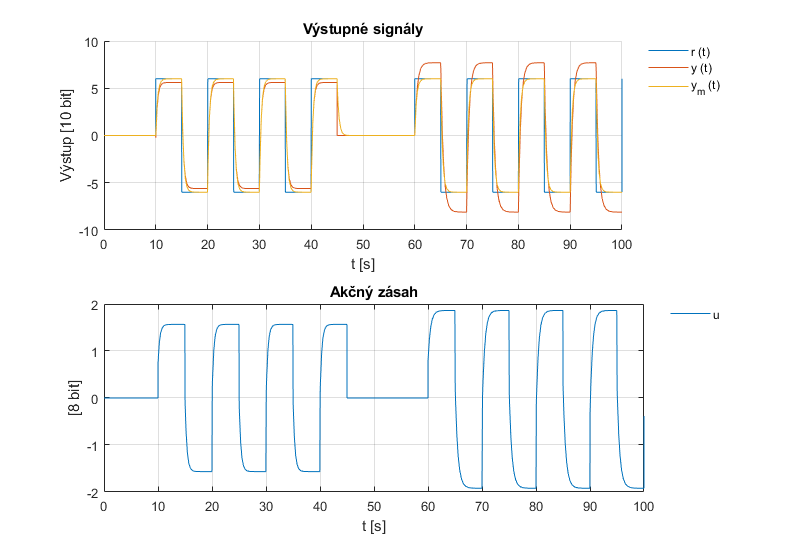

f1 = figure('Position', [100 100 900 600]);
subplot(2,1,1);
hold on;
plot(out.tout,out.r.Data,'DisplayName','r (t)');
plot(out.tout,out.y.Data,'DisplayName','y (t)');
plot(out.tout,out.ym.Data,'DisplayName','y_m (t)');
hold off;
xlabel('t [s]');ylabel('Výstup [10 bit]');grid on; title('Výstupné signály');legend('Location',"bestoutside");
legend boxoff

subplot(2,1,2);
plot(out.tout,out.u.Data,'DisplayName','u');
xlabel('t [s]');ylabel('[8 bit]');grid on; title('Akčný zásah');legend('Location',"bestoutside");
legend boxoff;
saveas(f1, 'figures/f_09_mrc.eps', 'epsc')

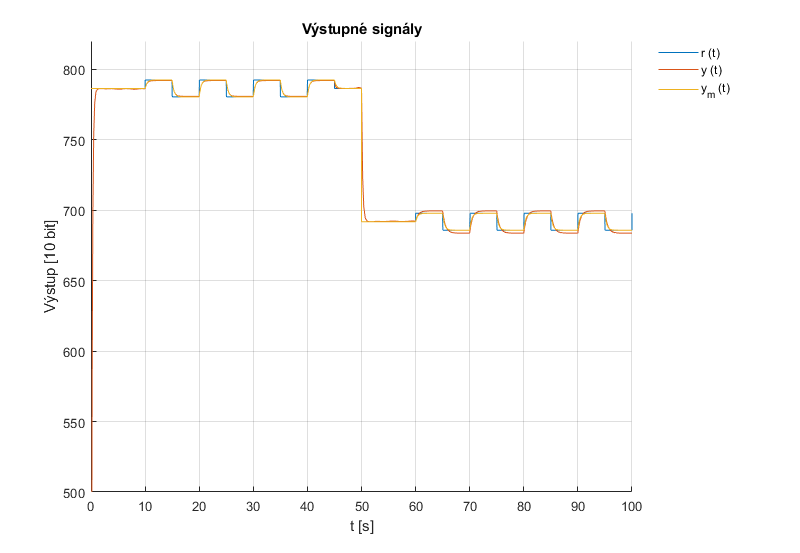


f2 = figure('Position', [100 100 900 600]);
hold on;
plot(out.tout,out.r_real.Data,'DisplayName','r (t)');
plot(out.tout,out.y_real.Data,'DisplayName','y (t)');
plot(out.tout,out.ym_real.Data,'DisplayName','y_m (t)');
hold off;
xlabel('t [s]');ylabel('Výstup [10 bit]');grid on; title('Výstupné signály');legend('Location',"bestoutside");
legend boxoff;
ylim([500,820]);
saveas(f2, 'figures/f_10_mrc_zmena_pb.eps', 'epsc')

## MRAC MIT riadenie

Simulacia a vykreslenie

upb = 206

upb = 206

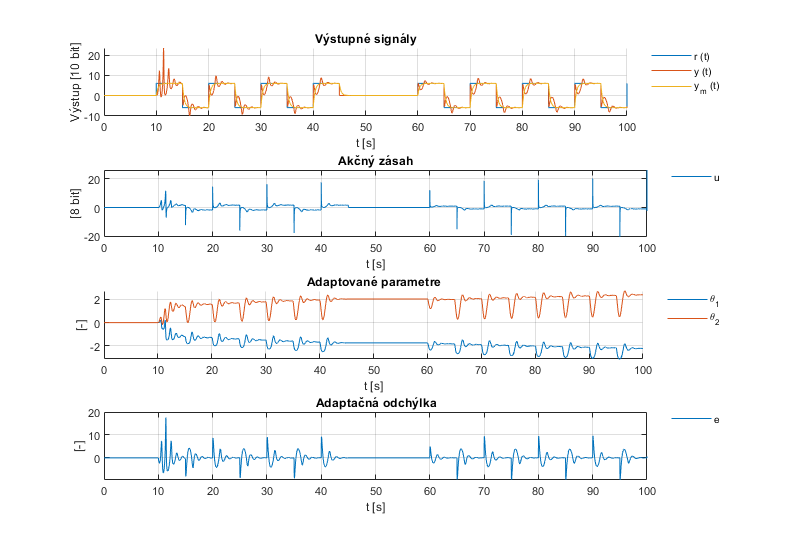

upb_delta = 56;
clf;
alpha = 0.7;
out = sim('MRAC_MIT_regulator.slx');

f3 = figure('Position', [100 100 900 600]);
subplot(4,1,1);
hold on;
plot(out.tout,out.r.Data,'DisplayName','r (t)');
plot(out.tout,out.y.Data,'DisplayName','y (t)');
plot(out.tout,out.ym.Data,'DisplayName','y_m (t)');
hold off;
xlabel('t [s]');ylabel('Výstup [10 bit]');grid on; title('Výstupné signály');legend('Location',"bestoutside");
legend boxoff

subplot(4,1,2);
plot(out.tout,out.u.Data,'DisplayName','u');
xlabel('t [s]');ylabel('[8 bit]');grid on; title('Akčný zásah');legend('Location',"bestoutside");
legend boxoff

subplot(4,1,3);
hold on;
plot(out.tout,out.theta1.Data,'DisplayName','\theta_1');
plot(out.tout,out.theta2.Data,'DisplayName','\theta_2');
hold off;
xlabel('t [s]');ylabel('[-]');grid on; title('Adaptované parametre');legend('Location',"bestoutside");
legend boxoff

subplot(4,1,4);
plot(out.tout,out.e.Data,'DisplayName','e');
xlabel('t [s]');ylabel('[-]');grid on; title('Adaptačná odchýlka');legend('Location',"bestoutside");
legend boxoff
saveas(f3, 'figures/f_11_mrc_mrac_adapt.eps', 'epsc')

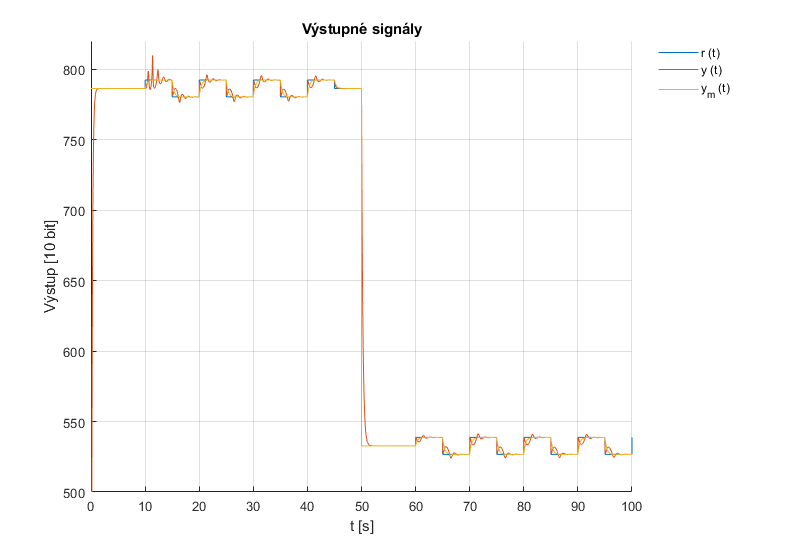


f4 =figure('Position', [100 100 900 600]);
hold on;
plot(out.tout,out.r_real.Data,'DisplayName','r (t)');
plot(out.tout,out.y_real.Data,'DisplayName','y (t)');
plot(out.tout,out.ym_real.Data,'DisplayName','y_m (t)');
hold off;
xlabel('t [s]');ylabel('Výstup [10 bit]');grid on; title('Výstupné signály');legend('Location',"bestoutside");
legend boxoff
ylim([500,820]);
saveas(f4, 'figures/f_12_mrc_mrac_zmena_PB.eps', 'epsc')